# `bedmap2_dist` documentation

The `bedmap2_dist` calculates distance in kilometers from any location(s) to any Bedmap2 mask type. This function may be useful for finding distance to the nearest grounding line. It is quite similar to the [ `dist2mask`](https://www.mathworks.com/matlabcentral/fileexchange/60246) function in the Antarctic boundaries dataset. 

This function requires Matlab's Image Processing Toolbox. 

An overview of Bedmap2 functions for AMT can be found in `bedmap_overview.mlx`.

## Syntax

## Description

`d = bedmap2_dist(lati,loni,reference)` returns distance(s) `d` from geo location(s) `lati,loni` to the nearest reference mask type. Distances are in kilometers. Options for reference can be

- `'grounded'` distance to nearest grounded ice. 

- `'ice sheet'` distance to nearest bit of ice sheet (grounded or ice shelf). 

- `'ice shelf'` distance to nearest floating ice shelf. 

- `'open ocean'` distance to nearest open ocean (returns nonzero distance on an ice shelf). 

- `'tidal'` distance to nearest ocean or ice shelf (e.g., returns zero at the center of Ross Ice Shelf). 

`d = bedmap2_dist(xi,yi,reference)` as above, but where input locations are in polar stereographic meters. Input coordinates are automatically determined by the `islatlon` function. 

## Example 1: Point location

Consider (80°S,175°W), which is somewhere in the middle of the Ross Ice Shelf. How far is it from grounded ice? 

bedmap2_dist(-80,-175,'grounded')

ans = 223.8825

That's about 224 km from (80°S,175°W) to the nearest grounding line. And how far from the nearest open ocean? 

bedmap2_dist(-80,-175,'open ocean')

ans = 175.8115

And of course (80°S,175°W) is in the middle of an ice shelf so all of these will be zero: 

bedmap2_dist(-80,-175,'ice shelf');
bedmap2_dist(-80,-175,'tidal');
bedmap2_dist(-80,-175,'ice sheet');

## Example 2: Scattered data

Suppose you've tagged some seals and you want to know how far they are from Antarctica's coast. Here's a map of your data: 

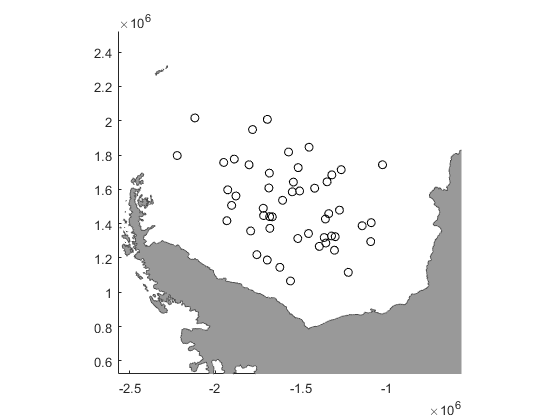

lat = -70+2.5*randn(50,1); 
lon = -45+5*randn(50,1); 

bedmap2('patchcoast','xy')
hold on
plotps(lat,lon,'ko');

mapzoomps(mean(lat),mean(lon),'mapwidth',2000)

Distance from the coast will be given using the `'ice sheet'` reference: 

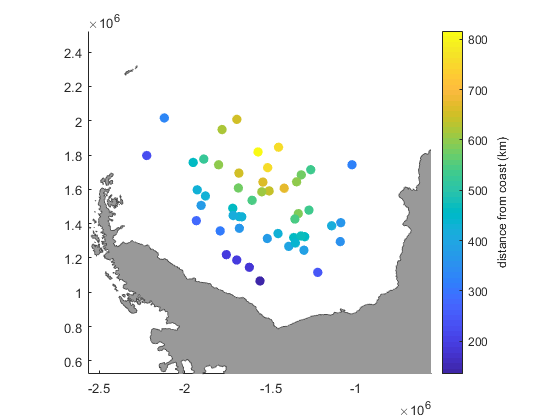

d = bedmap2_dist(lat,lon,'ice sheet'); 
scatterps(lat,lon,50,d,'filled')

cb = colorbar; 
ylabel(cb,' distance from coast (km) ')

## References

If this function is useful for you, please cite the following: 

Fretwell, P., et al. "Bedmap2: improved ice bed, surface and thickness datasets for Antarctica." The Cryosphere 7.1 (2013). [http://dx.doi.org/10.5194/tc-7-375-2013](http://dx.doi.org/10.5194/tc-7-375-2013) 

Greene, C. A., Gwyther, D. E., & Blankenship, D. D. Antarctic Mapping Tools for Matlab.  *Computers & Geosciences*. 104 (2017) pp.151-157. [doi:10.1016/j.cageo.2016.08.003](http://dx.doi.org/10.1016/j.cageo.2016.08.003).

## Author Info

This function was written by [Chad A. Greene](http://www.chadagreene.com) of the University of Texas at Austin's Institute for Geophyiscs (UTIG) in December 2015. Drop me a line if you have any questions or comments. 